# Operaciones arreglo (elemento a elemento)

## Operaciones elementales

### Ejercicio 1

Determinar la hipotenusa de un triángulo rectángulo isósceles. Los valores del cateto van desde $1$ hasta $100$.

Utilizar el teorema de pitágoras


$$c^2 =a^2 +b^2$$


donde $c$ es la hipotenusa y $a$, $b$ son los lados del triángulo rectángulo.

### Solución

a=1:100;
b=1:100;
c=sqrt(a.^2 + b.^2)

c =     1.4142    2.8284    4.2426    5.6569    7.0711    8.4853    9.8995   11.3137   12.7279   14.1421   15.5563   16.9706   18.3848   19.7990   21.2132   22.6274   24.0416   25.4558   26.8701   28.2843   29.6985   31.1127   32.5269   33.9411   35.3553   36.7696   38.1838   39.5980   41.0122   42.4264   43.8406   45.2548   46.6690   48.0833   49.4975   50.9117   52.3259   53.7401   55.1543   56.5685   57.9828   59.3970   60.8112   62.2254   63.6396   65.0538   66.4680   67.8823   69.2965   70.7107


### Ejercicio 2

Una medida de la obesidad se determina mediante el índice de masa corporal (IMC), que se calcula dividiendo la masa de una persona, $m$, por el cuadrado de su estatura, $h$.


$$\textrm{IMC}=\frac{m}{h^2 }$$


La masa está en kilogramos y la estatura en metros.

Un médico de la capital desea saber el IMC de sus pacientes. Para esto, toma una muestra de 50 pacientes y guarda sus datos en el archivo `Tema08_Auxiliar_Datos.mat`. Este archivo contiene una matriz en la que la primera fila representa la masa de cada paciente, en kilogramos, y la segunda fila representa la altura en metros.

En base a la gráfica, ¿cuántos pacientes de la muestra no están saludables? También calcula tu IMC y determina tu nivel de obesidad.

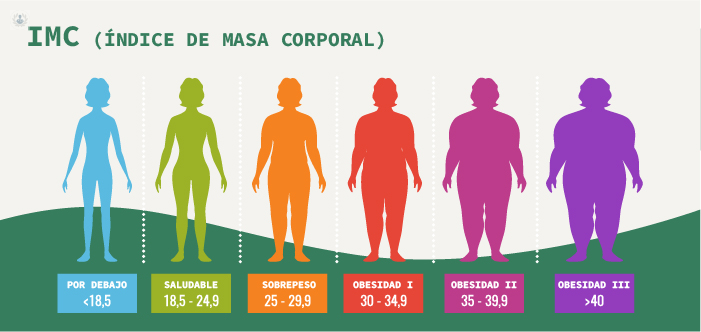

*Tomado de *[*TOPDOCTORS*](https://www.topdoctors.mx/diccionario-medico/indice-de-masa-corporal-imc#)*.*

### Solución

clc
load Tema08_Auxiliar_Datos.mat
%usaremos la varibale datos 
datos

datos =    52.0000   77.0000   51.0000   52.0000   71.0000   53.0000   83.0000   83.0000   79.0000   56.0000   77.0000   71.0000   89.0000   76.0000   82.0000   68.0000   67.0000   83.0000   53.0000   55.0000   57.0000   66.0000   84.0000   82.0000   52.0000   66.0000   71.0000   67.0000   76.0000   75.0000   61.0000   67.0000   50.0000   90.0000   56.0000   54.0000   65.0000   58.0000   70.0000   63.0000   89.0000   87.0000   52.0000   80.0000   61.0000   67.0000   72.0000   88.0000   67.0000   90.0000
    1.6200    1.7800    1.7700    1.7200    1.7800    1.7700    1.5700    1.5500    1.9000    1.5700    1.5100    1.7300    1.8600    1.7700    1.5700    1.6500    1.6800    1.9000    1.5600    1.8500    1.7600    1.6500    1.5700    1.6700    1.6900    1.5400    1.7400    1.5900    1.6500    1.7300    1.6000    1.6100    1.7500    1.6000    1.8300    1.9000    1.7900    1.6400    1.7300    1.5400    1.8700    1.8600    1.8300    1.6000    1.7400    1.5000    1.6700    1.6200    1.5600 

IMC = datos(1, :) ./ (datos(2, :).^2)

IMC =    19.8141   24.3025   16.2788   17.5771   22.4088   16.9172   33.6728   34.5473   21.8837   22.7190   33.7704   23.7228   25.7255   24.2587   33.2671   24.9770   23.7387   22.9917   21.7784   16.0701   18.4013   24.2424   34.0785   29.4023   18.2066   27.8293   23.4509   26.5021   27.9155   25.0593   23.8281   25.8478   16.3265   35.1562   16.7219   14.9584   20.2865   21.5645   23.3887   26.5643   25.4511   25.1474   15.5275   31.2500   20.1480   29.7778   25.8166   33.5315   27.5312   36.5126


fueraRango = (IMC <18.5) | (IMC > 24.9);
noSaludables = sum(fueraRango);
noSaludables

noSaludables = 33

### Ejercicio 3

La serie de Taylor de la función exponencial se define como


$$e^x =1+x+\frac{x^2 }{2!}+\frac{x^3 }{3!}+\cdots =\sum_{n=0}^{\infty } \frac{x^n }{n!}$$


Evaluar la serie de Taylor para $x=1$ con 5 términos de expansión de la serie.

**Recomendación 1:** Primero sería ideal crear vectores linealmente espaciados que representen las potencias y los denominadores, luego se podría evaluar la serie para el valor deseado utilizando operaciones arreglo.

**Recomendación 2:** La función `factorial` permite determinar el factorial de un número.

**Nota 1:** Para verificar el resultado se puede utilizar la función `exp` (consultar la documentación).

**Nota 2:** No utilizar bucles dado que todavía no se los ha estudiado.

### Solución

%numero maximo 
nf=4;
%valor inicial 
ni=0;
%valor dado 
x=1;
%vector de elementos 
v=ni:nf

v =      0     1     2     3     4


%Suma de Taylor 
Taylor=x.^v./factorial(v)

Taylor =     1.0000    1.0000    0.5000    0.1667    0.0417


teorico=sum(Taylor)

teorico = 2.7083

%comprabacion 
real=exp(1)

real = 2.7183